## Sigma ellipse 2D

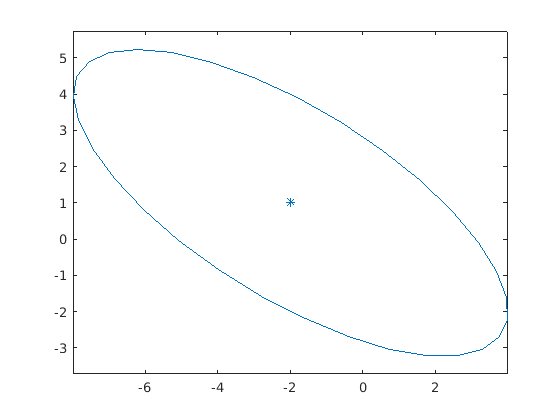

%Here we give parameters for a Gaussian density. The parameter mu is the mean, and P is the covariance matrix.
mu = [-2; 1];
P = [4, -2; -2 2];

%Call your function.
xy = sigmaEllipse2D(mu, P);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure(1);
h1 = plot(xy(1,:), xy(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);
hold off

mu = 5*randn(2,1);
s = 2*rand(2);
P = s'*s;
level = 1;
npoints = 100+round(25*rand)

npoints = 114

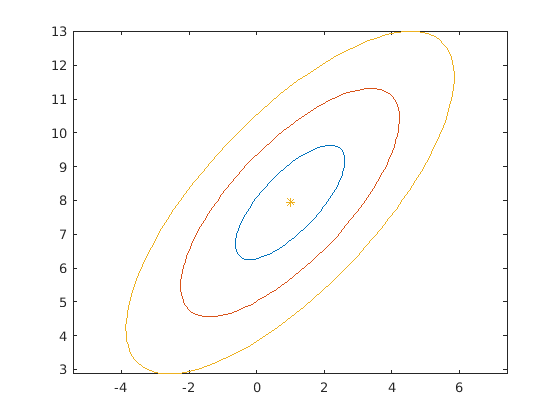

xy1 = sigmaEllipse2D(mu, P, level, npoints);
level = 2;
xy2 = sigmaEllipse2D(mu, P, level, npoints);
level = 3;
xy3 = sigmaEllipse2D(mu, P, level, npoints);
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure(1);
h2 = plot(xy1(1,:), xy1(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
h2 = plot(xy2(1,:), xy2(2,:));
h2 = plot(xy3(1,:), xy3(2,:));
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h2.Color);

n = size(xy1,2)

n = 114

assert(npoints == n, 'Number of generated points should be controlled by the fourth input argument')